# Legame spazio degli stati - funzione di trasferimento

Il controllo nello spazio degli stati è riscrivibile come funzione di trasferimento

Lo stato aumentato complessivo deve compredendere $x_d$ e $x_i$.


$$x_c=[x; x_d; x_i]$$


Il sistema osservatore-controllore nel seguente modo:


$$x(k+1)=Ax(k)+B(u(k)+x_d(k))$$



$$x_d(k+1)=x_d(k)$$



$${x}_i(k+1)=x_i(k)+Ts(r-y)=x_i(k)+Ts(r-Cx)$$



$$y(k)=Cx(k)$$



$$u(k)=H x_i(k)-K x(k)$$


Ottenendo le matrici

run('C:\projects\didattica\LaboratorioAutomatica\controllo_spazio_degli_stati\spazio_stati_integratore_discreto_LQ.mlx')
Ac=[Ao-Bo*[K 0]-L*Co Bo*H;-Co*Ts 1];
Bc=[[zeros(n,1);0;Ts] [L;0]];
Cc=[-[K 0] H];
Dc=[0 0];

Possiamo scrivere il sistema osservatore e controllore nel seguente modo (gli ingressi sono $r$ e $y$), uscita $u$

regulator=ss(Ac,Bc,Cc,Dc,Ts);
regulator.InputName={'r','y'};
regulator.OutputName={'u'};
regulator.StateName={'x1','x2','x3','x4','xd','xi'}


regulator =
 
  A = 
              x1         x2         x3         x4         xd         xi
   x1   -0.03115   0.008751  0.0009071  -0.000207  2.477e-05     0.7222
   x2    -0.7921      0.995  2.996e-06  0.0009965  4.553e-08   0.001327
   x3     -314.6      17.32     0.8072    -0.4031    0.04921       1435
   x4      36.88     -9.913     0.0074     0.9907  0.0001569      4.574
   xd     -27.61          0          0          0          1          0
   xi     -0.001          0          0          0          0          1
 
  B = 
            r       y
   x1       0       1
   x2       0   0.797
   x3       0   252.8
   x4       0  -27.11
   xd       0   27.61
   xi   0.001       0
 
  C = 
             x1         x2         x3         x4         xd         xi
   u     -259.2     -644.9     -3.115     -8.992          0  2.916e+04
 
  D = 
      r  y
   u  0  0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



Nelle funzioni di trasferimento di norma i controllori prendono come ingresso l'errore $e=r-y$ al posto di $y$. Cambio le variabili

T=ss([1 0;1 -1]);
T.InputName={'r','e'};
T.OutputName={'r','y'}


T =
 
  D = 
       r   e
   r   1   0
   y   1  -1
 
Static gain.



regulator2=regulator*T


regulator2 =
 
  A = 
              x1         x2         x3         x4         xd         xi
   x1   -0.03115   0.008751  0.0009071  -0.000207  2.477e-05     0.7222
   x2    -0.7921      0.995  2.996e-06  0.0009965  4.553e-08   0.001327
   x3     -314.6      17.32     0.8072    -0.4031    0.04921       1435
   x4      36.88     -9.913     0.0074     0.9907  0.0001569      4.574
   xd     -27.61          0          0          0          1          0
   xi     -0.001          0          0          0          0          1
 
  B = 
            r       e
   x1       1      -1
   x2   0.797  -0.797
   x3   252.8  -252.8
   x4  -27.11   27.11
   xd   27.61  -27.61
   xi   0.001       0
 
  C = 
             x1         x2         x3         x4         xd         xi
   u     -259.2     -644.9     -3.115     -8.992          0  2.916e+04
 
  D = 
      r  e
   u  0  0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



Riscrivo il sistema nella forma zpk

regulator2_zpk=zpk(regulator2)


regulator2_zpk =
 
  From input "r" to output "u":
    -1287.7 (z-1) (z^2 - 1.978z + 0.9787) (z^2 - 1.926z + 0.9699)
  -----------------------------------------------------------------
  (z-0.9962) (z-1) (z^2 - 1.923z + 0.9404) (z^2 - 0.8427z + 0.2619)
 
  From input "e" to output "u":
  1316.9 (z-0.9787) (z^2 - 1.98z + 0.9803) (z^2 - 1.924z + 0.9733)
  -----------------------------------------------------------------
  (z-0.9962) (z-1) (z^2 - 1.923z + 0.9404) (z^2 - 0.8427z + 0.2619)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.



Il segnale che moltiplica il setpoint (è un feedforward del setpoint) è

Cr=regulator2_zpk(1);

Il controllore in retroazione è

Ce=regulator2_zpk(2);

Il controllore di feedforward posso riscriverlo come filtro sul setpoint

Cf=minreal(1+Cr/Ce);

Calcolo la risposta del sistema in anello chiuso

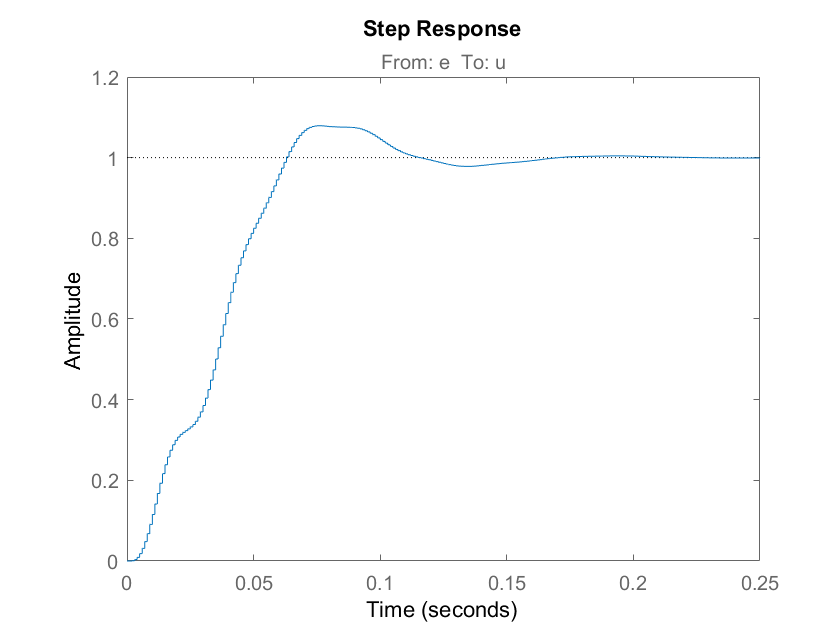

step(Cf*feedback(Pd*Ce,1))

I margini di stabilità

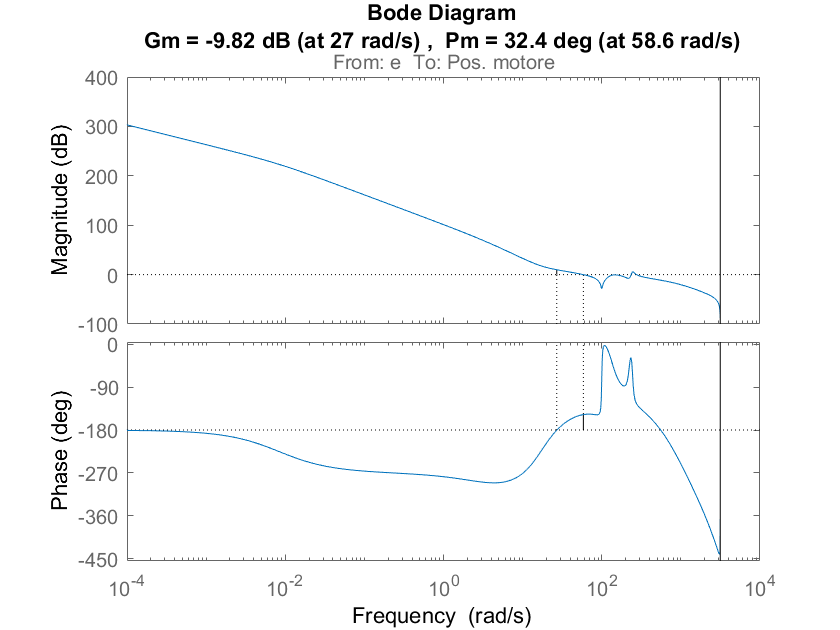

margin(Pd*Ce)

allmargin(Pd*Ce)

ans = struct with fields:
     GainMargin: [6.2513e-18 0.3229 3.7084]
    GMFrequency: [9.4151e-06 27.0409 556.5899]
    PhaseMargin: [32.4493 151.0696 55.1711]
    PMFrequency: [58.6131 235.4196 274.9459]
    DelayMargin: [9.6625 11.1998 3.5022]
    DMFrequency: [58.6131 235.4196 274.9459]
         Stable: 1


I diagrammi di Bode

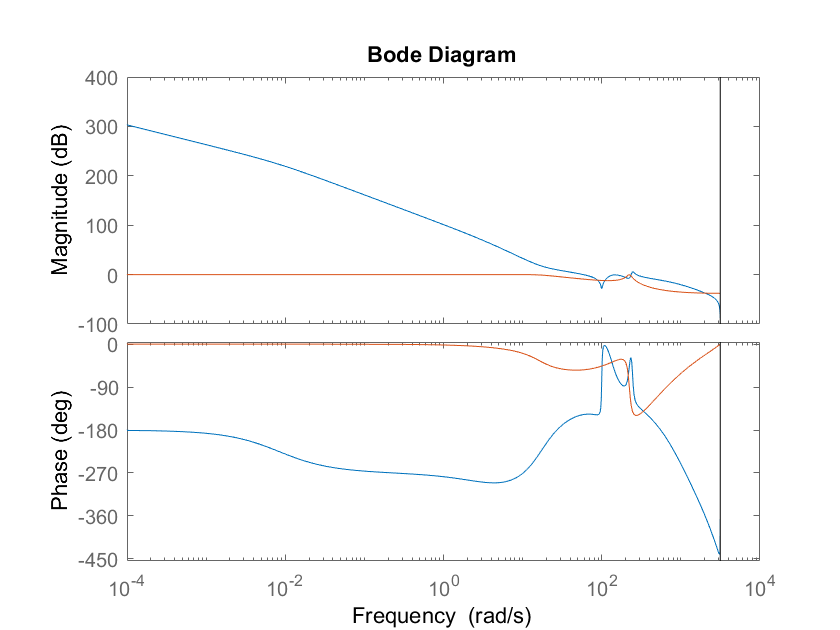

bode(Pd*Ce,Cf)